This file is for calculating co-variation

CAmotif='ELLETFNHTEVAYP'

CAmotif = 'ELLETFNHTEVAYP'

ExtendedA6motif='LQPKGIYGELCIGGAGLARGYL';

Ams=(1:0.5:10)';
mtypelist=[
    num2cell([Atype*ones(size(Ams)),Ams],2);
    {[Ttype,0.5]};
    {[Ttype,1]};
    {[Ctype,0.5;
    Etype,0.5]};% after this one, is breakable
    num2cell([Ctype*ones(size(Ams)),Ams],2);
    {[Atype,0.5]};
    num2cell([Atype*ones(size(Ams)),Ams],2);
    {[Ttype,0.5]};
    {[Ttype,1]};
    ];
nextbreakable=23;

% fill in the alignment


% use the regions as:
touseregins=1:20;%find(cEK_regions.fateid>0);% alive % active

motif_mats=[];
todelline=[];
for i=1:length(mtypelist)
    allowedtypes=mtypelist{i};
    mlist_in_type=find(ismember(motif_struct.motifid_mat_list,allowedtypes,'rows') & ismember(motif_struct.region_id,touseregins));
    
    if i==1
        motif_mats=mlist_in_type;
    else 
        if ~ismember(i,nextbreakable) % must be exactly the same one
            % attach it to the previous one
            shouldbe=motif_mats(:,i-1)+1;
        
            goodlist=ismember(shouldbe,mlist_in_type);
            motif_mats(goodlist,i)=shouldbe(goodlist);
            
            badlist=find(~goodlist);
            todelline=[todelline;badlist];
        else % within one module , not necessarily after.
            for k=1:size(motif_mats,1)
                lastmid=motif_mats(k,i-1);
                if lastmid>0
                    % which is the closest one with this
                    candidate_loc=find(motif_struct.region_id(mlist_in_type)==motif_struct.region_id(lastmid) & mlist_in_type>lastmid & mlist_in_type<(lastmid+22));
                    if ~isempty(candidate_loc)
                       motif_mats(k,i)=min(mlist_in_type(candidate_loc));
                    else
                       todelline=[todelline;k];
                    end
                end % for k=1:size(motif_mats,1)
            end
        end %  else % within one module , not necessarily after.
    end
end
todelline=unique(todelline);

motif_mats(todelline,:)=[];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% extract the alignment
tot_msa=[];
motifid_mdist_gap=[]; % alone the whole
for m=1:size(motif_mats,2)
    m_mat=motif_mats(:,m);
    
    thism_type=mtypelist{m};
    if size(thism_type,1)==1
    
        motifloc=find(ismember(motif_struct.uni_motifids,thism_type,'rows'));
        diststruct_mlist=motif_struct.motif_diststruct{motifloc}.mlist;
        diststruct_olist=motif_struct.motif_diststruct{motifloc}.olist;
        diststruct_distm=squareform(motif_struct.motif_diststruct{motifloc}.distline);
        diststruct_msa=motif_struct.motif_diststruct{motifloc}.msa;
        
        
          
        % only extract these in "good regions"
        diststruct_list_2_use=nan*zeros(size(m_mat));
        for i=1:length(diststruct_list_2_use) % hereya
            loc=find(diststruct_mlist==m_mat(i));
            if ~isempty(loc)
                diststruct_list_2_use(i)=loc;  % hereya   
            else
                error('seq not here');
            end
            diststruct_list_2_use(i)=loc;
        end % hereya
    
        
         msa=diststruct_msa(diststruct_list_2_use,:);% hereya
    
    else
        % get their msa
        seqs=motif_struct.seq_list(m_mat);
        tempname=sprintf('./output1/Fig4mlx_%d_%d_%d',m,size(seqs,1),size(seqs,2));
        
        test_header = cellstr(num2str([1:length(seqs)]'));
        fastawrite([tempname,'.fasta'],test_header,seqs);
        command = ['clustalo -i ',pwd,tempname,'.fasta -o ',pwd,tempname,'_1.fasta --outfmt fasta --output-order input-order'];
        system(command);
                
            try
                msa=[];
                raw = fastaread([tempname,'_1.fasta']);
                for ii = 1:length(raw)
                    msa=[msa;raw(ii).Sequence];
                end
            catch ME
                msa = multialign(seqs,'ScoringMatrix',scoringlist{2});
            end
            
           
            
        
    end
    % extract the multiple alignment
   
    nanpercent=sum(msa=='-',1)/size(msa,1);
   
   
    
    [condiH_eachsite,totalH,meandist_eachsite]=ZL_MotifbyConveration(msa,'aa',[],0);
    
    
    %%%%%%%%%%%%% add data
    addeddata=[m*ones(size(meandist_eachsite));
        meandist_eachsite;
        nanpercent];
    motifid_mdist_gap=[motifid_mdist_gap,addeddata];
    
    
    tot_msa=[tot_msa,msa];
end

'clustalo' 不是内部或外部命令，也不是可运行的程序 
或批处理文件。 




% find the position for the extended G6

size(msa)

ans =     88    11


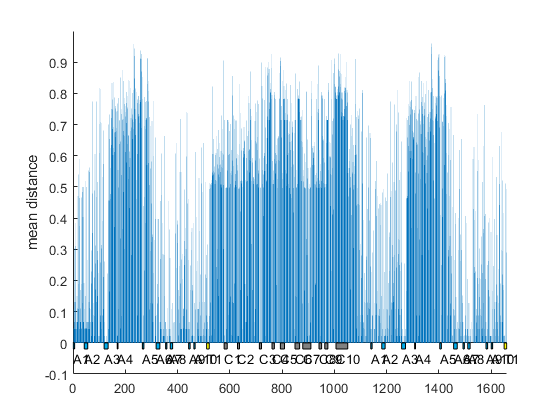


%%%% plot out the result
gapthresh=0.75;
column_to_keep=find(motifid_mdist_gap(end,:)<gapthresh);

figure;
hold on;
bar(motifid_mdist_gap(2,column_to_keep))
ylabel('mean distance')

for i=1:length(mtypelist)
     allowedtypes=mtypelist{i};
     if size(allowedtypes,1)==1
        dtype=allowedtypes(1);
        mtype=allowedtypes(2);
        if abs(mtype-round(mtype))<0.1 % is a motif
            locs=find(motifid_mdist_gap(1,column_to_keep)==i);
            colorcode=cEK_omains.colorcode(dtype,:);  
            textstr=[cEK_omains.domaintypelist{dtype},num2str(mtype)];
            
            ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.02,colorcode);
            ph.EdgeColor='k';
            text((locs(1)),-0.05,textstr)
        
        end
     end
end
ylim([-0.1,1]);


size(tot_msa)

ans =           88        2234


## Normalized mutual information 

gapthresh=0.75;
column_to_keep=find(motifid_mdist_gap(end,:)<gapthresh);



aa_freqs=seqprofile(tot_msa(:,column_to_keep));
H_eachsite=nansum(-1*aa_freqs.*log2(aa_freqs),1)

H_eachsite =          0    0.2183         0    0.8330    0.0914         0    0.2714    0.7373    0.3179         0    0.8924         0         0    0.0914    0.3200    0.2504    0.0914    0.0914    1.0173    1.2685    0.2183    0.4071    1.6922    0.7619         0    0.9694    0.0914    0.3651    0.0914    0.2504         0    1.1276    0.5193         0    0.2714    1.1023    1.0907    0.8694    0.0914    1.0966    0.0914    0.4873         0         0    0.2504    1.1728         0    0.3620         0    1.0675


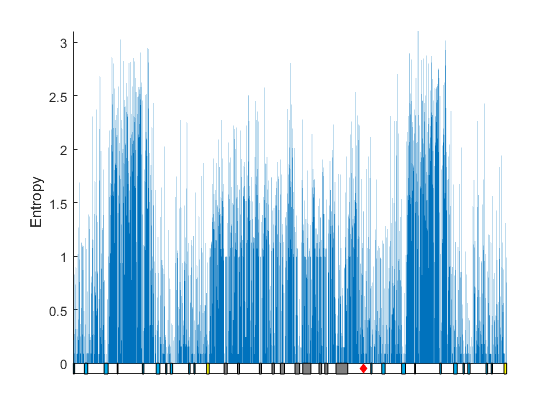



%%%% plot out the result


figure;
hold on;
bh=bar(H_eachsite,1); ylabel('Entropy')
%bar(motifid_mdist_gap(2,column_to_keep));ylabel('mean distance')
bh.LineStyle='none';

for i=1:length(mtypelist)
     allowedtypes=mtypelist{i};
     if size(allowedtypes,1)==1
        dtype=allowedtypes(1);
        mtype=allowedtypes(2);
        if abs(mtype-round(mtype))<0.1 % is a motif
            locs=find(motifid_mdist_gap(1,column_to_keep)==i);
            colorcode=cEK_omains.colorcode(dtype,:);  
            textstr=[cEK_omains.domaintypelist{dtype},num2str(mtype)];
            
            ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.1,colorcode);
            ph.EdgeColor='k';
            %text((locs(1)),-0.05,textstr)
        
        end
     end
end
ylim([-0.1,max(H_eachsite)]);

% get a concensus seq
CSeq_tot = seqconsensus(tot_msa(:,column_to_keep));


CA_AlignStruct = localalign(CSeq_tot, CAmotif,'NumAln',1);
CA_se=[CA_AlignStruct.Start(1,1),CA_AlignStruct.Stop(1,1)];

A6_AlignStruct = localalign(CSeq_tot, ExtendedA6motif,'NumAln',2);
A6_se=[A6_AlignStruct.Start(:,1),A6_AlignStruct.Stop(:,1)];


ms=30;
scatter(CA_se(2),-0.05,ms,'r','d','filled')
set(gca,'xtick',[])



%%%%%% calculate the mutual information each site
if ~exist('joint_H','var')
    joint_H=zeros(length(column_to_keep));
    for i=1:length(column_to_keep)
        for j=1:(i-1)
            strs=tot_msa(:,[column_to_keep(i),column_to_keep(j)]);
            strs(sum(strs=='-',2)>0,:)=[];
            tbm=tabulate(strs);
            freqs=cell2mat(tbm(:,3))/100;
            joint_H(i,j)=nansum(-1*freqs.*log2(freqs));
            joint_H(j,i)=joint_H(i,j);
        end
    end
end

% the mutual information
mulinfor_m=repmat(H_eachsite,length(column_to_keep),1) + repmat(H_eachsite,length(column_to_keep),1)' -joint_H;
for i=1:length(column_to_keep)
    mulinfor_m(i,i)=nan;
end



use: [https://academic.oup.com/bioinformatics/article/24/3/333/253952](https://academic.oup.com/bioinformatics/article/24/3/333/253952)

Dunn, Stanley D., Lindi M. Wahl, and Gregory B. Gloor. "Mutual information without the influence of phylogeny or entropy dramatically improves residue contact prediction." *Bioinformatics* 24.3 (2008): 333-340.

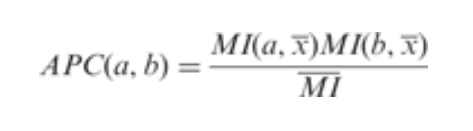

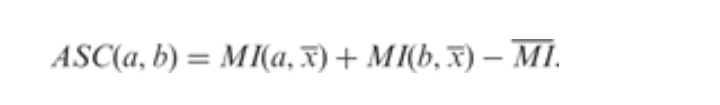

mean_MI_byposition=nanmean(mulinfor_m);
mean_MI=mean(mean_MI_byposition)

mean_MI = 0.1612

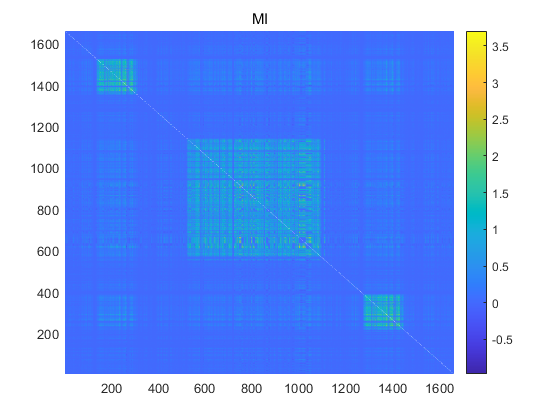


APC=mean_MI_byposition'*mean_MI_byposition/mean_MI;
MIp=mulinfor_m-APC;

ASC=repmat(mean_MI_byposition,length(mean_MI_byposition),1)+repmat(mean_MI_byposition,length(mean_MI_byposition),1)'-mean_MI;
MIa=mulinfor_m-ASC;

figure;
Easypcolor_flip_LZY(mulinfor_m,'u');
title('MI')
colorbar

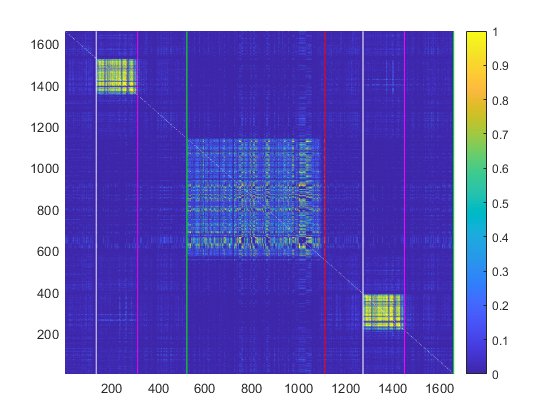



% A3 and T motif
figure;
colormap('default')
Easypcolor_flip_LZY(MIp,'u');
title('')
caxis([0,1])
colorbar
for i=1:length(mtypelist)
     allowedtypes=mtypelist{i};
     if size(allowedtypes,1)==1
        dtype=allowedtypes(1);
        mtype=allowedtypes(2);
        if abs(mtype-round(mtype))<0.1 % is a motif
            if (dtype==Atype && ismember(mtype,[3]))|(dtype==Ttype )
            locs=find(motifid_mdist_gap(1,column_to_keep)==i);
            colorcode=cEK_omains.colorcode(dtype,:);  
            textstr=[cEK_omains.domaintypelist{dtype},num2str(mtype)];
            
            if dtype==Ttype
                colorcode=[0,1,0]; % green
            else
                colorcode=[1,1,1]; % white
            end
            plot(max(locs)*[1,1],[0,length(mean_MI_byposition)],'Color',colorcode)
            
            %ph=patch([locs(1),locs(end),locs(end),locs(1)],[0,0,-1,-1]*0.02,colorcode);
            %ph.EdgeColor='k';
            %text((locs(1)),-0.05,textstr)
            
            end
        end
     end
end

% plot additional motifs

locs=A6_se(:,1); % start of extended A6
for i=1:2
    plot(locs(i)*[1,1],[0,length(mean_MI_byposition)],'color',[1,0,1]); % magenta
end
        

% 
 plot(CA_se(2)*[1,1],[0,length(mean_MI_byposition)],'r')


print('./Figures/Fig4heatmap.png','-dpng','-r400')